clear; close all;

[ProgressClassFile, ProgressClassFolder, tf] = uigetfile("F:\YuLab\Work\GPS\Data\*.mat");
if ~tf
    return;
end
ProgressClassPath = fullfile(ProgressClassFolder, ProgressClassFile);

load(ProgressClassPath);

FigFolder = fullfile(ProgressClassFolder, "TestFigs");
if ~isfolder(FigFolder)
    mkdir(FigFolder);
end

MixedFP = obj.MixedFP;


pdf_control = cell(3, 2);
pdf_chemo = cell(3, 2);
pdf_control_ci = cell(3, 2);
pdf_chemo_ci = cell(3, 2);

cdf_control = cell(3, 2);
cdf_chemo = cell(3, 2);
cdf_control_ci = cell(3, 2);
cdf_chemo_ci = cell(3, 2);

bins = 0:0.001:2;
band_width = 0.05;
n_boot = 1000;

kde_pdf = @(x) ksdensity(x, bins, 'Function', 'pdf', 'Bandwidth', band_width);
kde_cdf = @(x) ksdensity(x, bins, 'Function', 'cdf', 'Bandwidth', band_width);


valid = 1;
for fp = 1:3
    for p = 1:2

        disp([fp, p]);

        data_control = obj.HDSortedControl{fp, p};
        data_chemo = obj.HDSortedChemo{fp, p};
        switch valid
            case 1
                data_control = data_control(data_control>0.5);
                data_chemo = data_chemo(data_chemo>0.5);
        end

        pdf_control{fp, p} = kde_pdf(data_control);
        pdf_chemo{fp, p} = kde_pdf(data_chemo);
        pdf_control_ci{fp, p} = bootci(n_boot, {kde_pdf, data_control}, 'type', 'cper');
        pdf_chemo_ci{fp, p} = bootci(n_boot, {kde_pdf, data_chemo}, 'type', 'cper');

        cdf_control{fp, p} = kde_cdf(data_control);
        cdf_chemo{fp, p} = kde_cdf(data_chemo);
        cdf_control_ci{fp, p} = bootci(n_boot, {kde_cdf, data_control}, 'type', 'cper');
        cdf_chemo_ci{fp, p} = bootci(n_boot, {kde_cdf, data_chemo}, 'type', 'cper');
    end
end

     1     1
     1     2
     2     1
     2     2
     3     1
     3     2


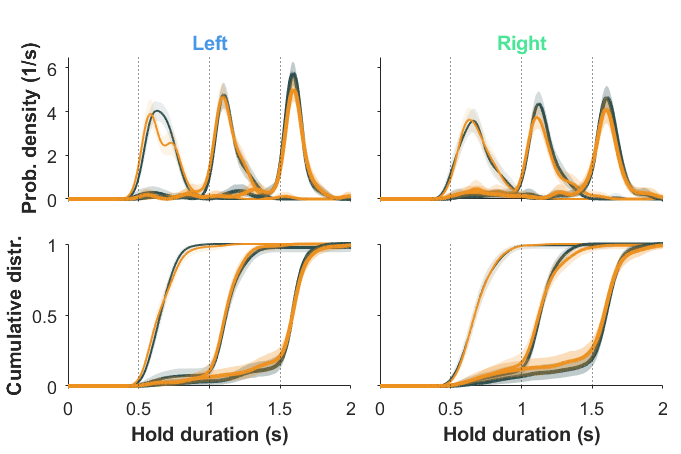

fig = figure(34); clf(34);
set(fig, 'Visible', 'on', 'Units', 'centimeters', 'Position', [5 5 12 8], 'Color', 'w');

set_fig_title(fig, 'ThreeFPSRT', 'FontSize', 11);

ax = cell(2,2);

for p = 1:2

    ax{1,p} = axes(fig, 'Units', 'centimeters', 'Position', [1.2+(p-1)*5.5 4.5 5 2.5], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');
    ax{2,p} = axes(fig, 'Units', 'centimeters', 'Position', [1.2+(p-1)*5.5 1.2 5 2.5], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

    for fp = 1:3
        xline(ax{1,p}, MixedFP, 'LineWidth', .5, 'LineStyle', ':');
        fill(ax{1,p}, [bins flip(bins)], [pdf_control_ci{fp, p}(1,:) flip(pdf_control_ci{fp, p}(2,:))], 'y', ...
            'FaceColor', GPSColor.Control, 'FaceAlpha', .1*fp, 'EdgeColor', 'none');
        plot(ax{1,p}, bins, pdf_control{fp, p}, ...
            'color', GPSColor.Control, 'linewidth', .5+.5*fp, 'LineStyle', '-');
        fill(ax{1,p}, [bins flip(bins)], [pdf_chemo_ci{fp, p}(1,:) flip(pdf_chemo_ci{fp, p}(2,:))], 'y', ...
            'FaceColor', GPSColor.Treat, 'FaceAlpha', .1*fp, 'EdgeColor', 'none');
        plot(ax{1,p}, bins, pdf_chemo{fp, p}, ...
            'color', GPSColor.Treat  , 'linewidth', .5+.5*fp, 'LineStyle', '-');


        xline(ax{2,p}, MixedFP, 'LineWidth', .5, 'LineStyle', ':');
        fill(ax{2,p}, [bins flip(bins)], [cdf_control_ci{fp, p}(1,:) flip(cdf_control_ci{fp, p}(2,:))], 'y', ...
            'FaceColor', GPSColor.Control, 'FaceAlpha', .1*fp, 'EdgeColor', 'none');
        plot(ax{2,p}, bins, cdf_control{fp, p}, ...
            'color', GPSColor.Control, 'linewidth', .5+.5*fp, 'LineStyle', '-');
        fill(ax{2,p}, [bins flip(bins)], [cdf_chemo_ci{fp, p}(1,:) flip(cdf_chemo_ci{fp, p}(2,:))], 'y', ...
            'FaceColor', GPSColor.Treat, 'FaceAlpha', .1*fp, 'EdgeColor', 'none');
        plot(ax{2,p}, bins, cdf_chemo{fp, p}, ...
            'color', GPSColor.Treat  , 'linewidth', .5+.5*fp, 'LineStyle', '-');

        drawnow;
    end
end

ax{1,1}.YLabel.String = "Prob. density (1/s)";
ax{1,1}.YLabel.FontWeight = "bold";

ax{1,1}.Title.String = "Left";
ax{1,1}.Title.Color = GPSColor.PortL;
ax{1,1}.Title.FontWeight = "bold";

ax{1,2}.Title.String = "Right";
ax{1,2}.Title.Color = GPSColor.PortR;
ax{1,2}.Title.FontWeight = "bold";

ax{1,1}.YLim(2) = max([ax{1,1}.YLim(2) ax{1,2}.YLim(2)]);
ax{1,1}.YLim(2) = .5 * (ceil(ax{1,1}.YLim(2)) + round(ax{1,1}.YLim(2)));
ax{1,2}.YLim(2) = ax{1,1}.YLim(2);

set(ax{1,1}, 'XLim', [0 2], 'XTickLabel', []);
set(ax{1,2}, 'XLim', [0 2], 'XTickLabel', [], 'YTickLabel', []);

ax{2,1}.XLabel.String = "Hold duration (s)";
ax{2,1}.YLabel.String = "Cumulative distr.";
ax{2,1}.XLabel.FontWeight = "bold";
ax{2,1}.YLabel.FontWeight = "bold";

ax{2,2}.XLabel.String = "Hold duration (s)";
ax{2,2}.XLabel.FontWeight = "bold";

set(ax{2,1}, 'XLim', [0 2]);
set(ax{2,2}, 'XLim', [0 2], 'YTickLabel', []);

switch valid
    case 0
        fig_name = sprintf("Test_%s_Distr_3FP_%s.jpg", obj.Task, obj.Subject);
    case 1
        fig_name = sprintf("Test_%s_Distr_3FP_valid_%s.jpg", obj.Task, obj.Subject);
end
fig_path = fullfile(FigFolder, fig_name);
saveas(fig, fig_path);